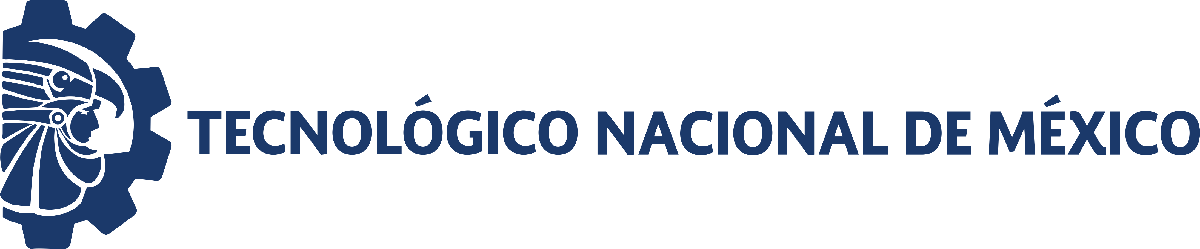                                 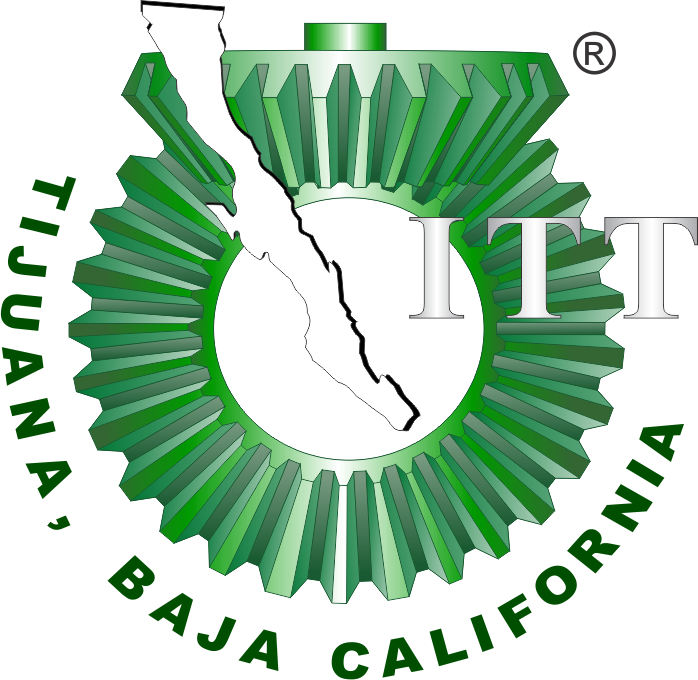

# **Proyecto Final: Sitema Endocrino - Hipotiroidismo**

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

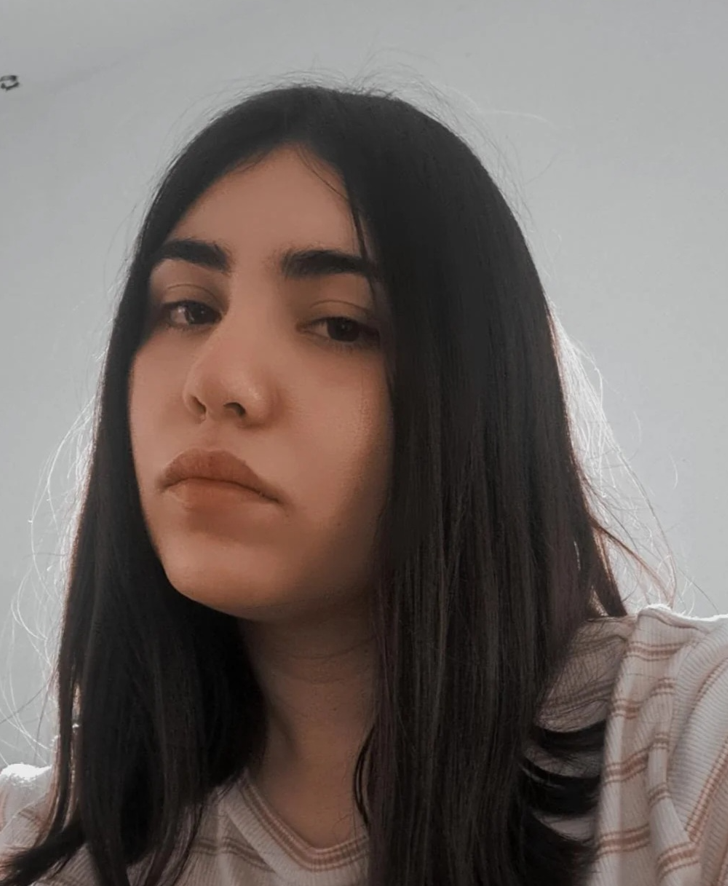

Nombre del alumno: **Damian Arroyo Perla Guadalupe**

Número de control: **21212150**

Correo institucional: **l21212150@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

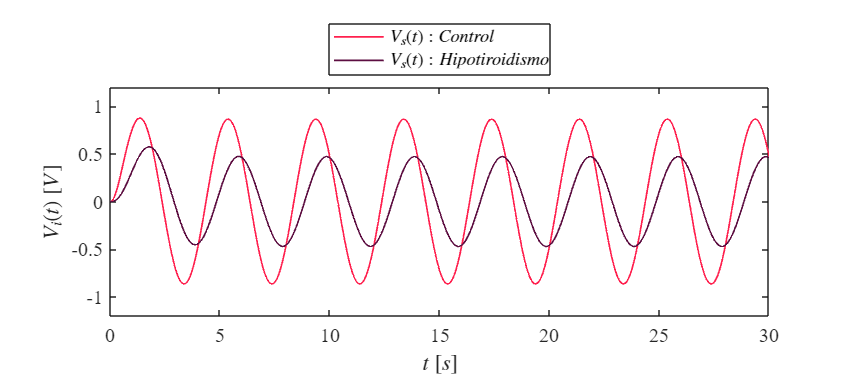

clc; clear; close all; warning('off','all')
tend = '30';
file = 'sysp7_LA';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
x = sim (file, parameters);
plotsignal1 (x.t, x.Vsx, x. Vsy)

## Caso: Hipotiroidismo

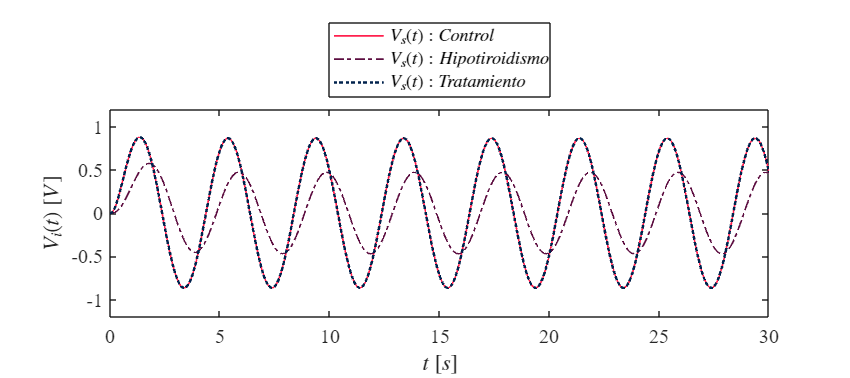

file = 'sysp7_LC';
open_system(file);
x = sim (file, parameters);
plotsignal (x.t, x.Vsx, x. Vsy, x.Vsz)

## Función

function plotsignal(t, Vsx, Vsy, Vsz)
set(figure(), 'Color', 'w')
set(gcf, 'Units', 'Centimeters', 'Position',[1,1,18,8])
set(gca, 'FontName', 'Times New Roman')
fontsize(12, 'points')
rosa = [255/255, 32/255, 78/255];
morado = [93/255, 14/255, 65/255];
azul = [0/255, 34/255, 77/255];
hold on; grid off; box on

t = t(:);
% Convertir objetos timeseries a arreglos numéricos
if isa(Vsx, 'timeseries'), Vsx = Vsx.Data(:); end
if isa(Vsy, 'timeseries'), Vsy = Vsy.Data(:); end
if isa(Vsz, 'timeseries'), Vsz = Vsz.Data(:); end


plot(t, Vsx, 'LineWidth', 1,'Color',rosa)
plot(t, Vsy, '-.', 'LineWidth', 1,'Color', morado)
plot(t, Vsz,':', 'LineWidth', 1.5,'Color', azul)
xlabel('$t$ $[s]$', 'Interpreter','Latex')
ylabel('$V_i (t)$ $[V]$', 'Interpreter','Latex')
L = legend('$V_s(t): Control$', '$V_s(t): Hipotiroidismo$', '$V_s(t): Tratamiento$');
set(L, 'Interpreter', 'latex', 'Location', 'northoutside', 'Box', 'on')

xlim([0, 30]); xticks(0:5:30)
ylim([-1.2, 1.2]); yticks(-2:0.5:2)
end

## Función dos

function plotsignal1(t, Vsx, Vsy)
set(figure(), 'Color', 'w')
set(gcf, 'Units', 'Centimeters', 'Position',[1,1,18,8])
set(gca, 'FontName', 'Times New Roman')
fontsize(12, 'points')
rosa = [255/255, 32/255, 78/255];
morado = [93/255, 14/255, 65/255];
hold on; grid off; box on

t = t(:);
% Convertir objetos timeseries a arreglos numéricos
if isa(Vsx, 'timeseries'), Vsx = Vsx.Data(:); end
if isa(Vsy, 'timeseries'), Vsy = Vsy.Data(:); end


plot(t, Vsx, 'LineWidth', 1,'Color',rosa)
plot(t, Vsy, 'LineWidth', 1,'Color', morado)
xlabel('$t$ $[s]$', 'Interpreter','Latex')
ylabel('$V_i (t)$ $[V]$', 'Interpreter','Latex')
L = legend('$V_s(t): Control$', '$V_s(t): Hipotiroidismo$');
set(L, 'Interpreter', 'latex', 'Location', 'northoutside', 'Box', 'on')

xlim([0, 30]); xticks(0:5:30)
ylim([-1.2, 1.2]); yticks(-2:0.5:2)

end